x = [0,10,10, -1, 10, 0];
y = [0,0,10, 12, 2, 0];
path = Path(x,y,4);
len = path.getLength()

len = 27.1501

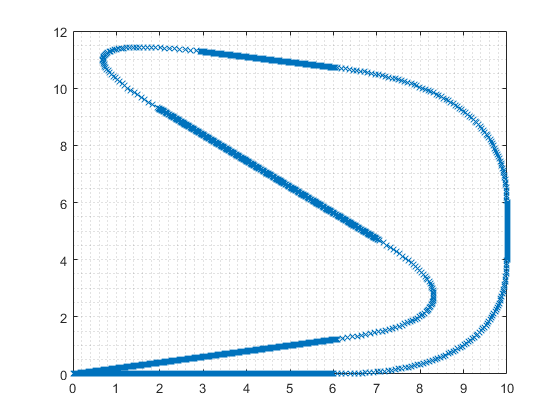

s = [0:.01:len];
[x1,y1] = path.getPoint(s);
figure();
plot(x1,y1,":x")
grid minor

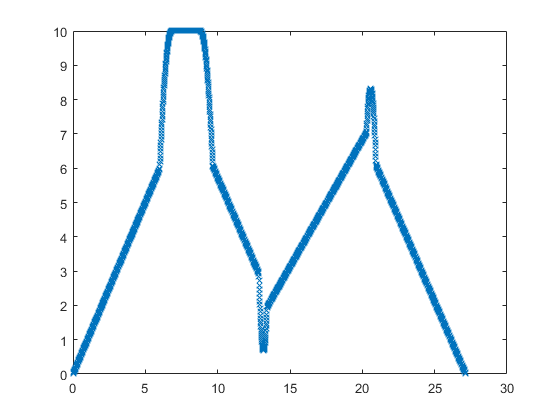


figure()
plot(s,x1,"x")

[xt,yt] = path.diff(s)

xt =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


yt =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


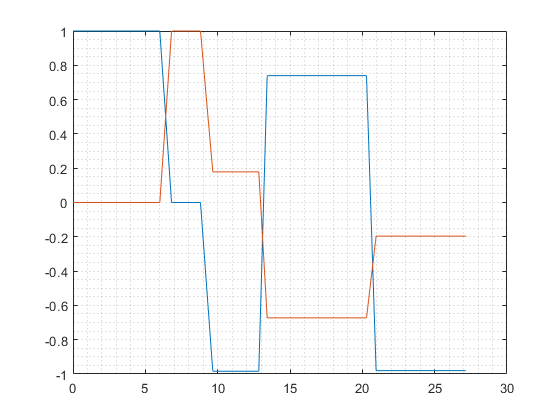


figure();
plot(s,xt);
hold on
plot(s,yt)
grid minor

b = BezierCurve([0,1,2], [0,0,1], 7)

b =   BezierCurve with properties:

      startPoint: [1×1 struct]
        endPoint: [1×1 struct]
               r: 7
              dt: 1.0000e-03
    controlPoint: [1×1 struct]
          length: 0.9507


b.diffAnalytical()

Abstract classes cannot be instantiated.  Class 'LinearSpline' inherits abstract methods or properties but does not implement them.  See the list of methods and properties that 'LinearSpline' must implement if you do not intend the class to be abstract.

Error in BezierCurve/diffAnalytical (line 90)
           obj = LinearSpline(x,y);

s= [0:0.01:b.length];
[x,y] = b.diff(s);
figure();
plot(s,y)
hold on
plot(s,x)

figure()
l = LinearSpline();

Not enough input arguments.

Error in LinearSpline (line 15)
            obj.startPoint = struct("x", x(1), "y", y(1));

s = [0: 0.01: l.getLength()]
[x,y] = l.getPoint(s)
plot(s,x)